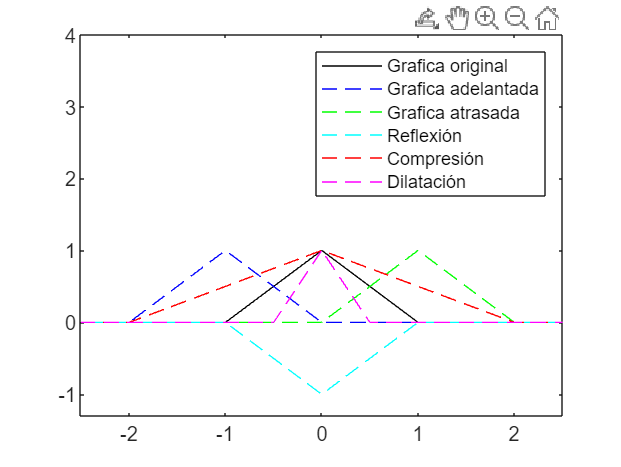

t = -10:0.01:10;

% Crear la función triangular unida utilizando la función rampa_unida
trg = rampa_unida(t + 1) - 2*rampa_unida(t) + rampa_unida(t-1);

% Graficas 
figure;
title('Función Delta de Dirac');
xlabel('Tiempo');
ylabel('\delta(t)');

% Graficar la función delta(t) original
plot(t, trg, "k", 'DisplayName', 'Grafica original');
axis([-2.5 2.5 -1.3 4]);
hold on

% Graficar la función delta(t) adelantada
plot(t-1, trg, "--b", 'DisplayName', 'Grafica adelantada');

% Graficar la función delta(t) atrasada
plot(t+1, trg, "--g", 'DisplayName', 'Grafica atrasada');

% Graficar la función delta(t) reflejada
plot(t, -trg, "--c", 'DisplayName', 'Reflexión');

% Graficar la función delta(t) comprimida
plot(t*2, trg, "--r", 'DisplayName', 'Compresión');

% Graficar la función delta(t) dilatada
plot(t/2, trg, "--m", 'DisplayName', 'Dilatación');

legend;